
$$\left\{ \begin{array}{c}
	u_t-au_{xx}=f\left( x,t \right) \,\,\left( x_1<x<x_2 \right) \,\,\left( t>0 \right)\\
	u\left( x,0 \right) =g_t\left( x \right) \,\,\left( x_1<x<x_2 \right)\\
	u\left( x_1,t \right) =g_1\left( t \right) , u\left( x_2,t \right) =g_2\left( t \right) \,\,\left( t>0 \right)\\
\end{array} \right.$$



$$0.1<x<\pi$$


x = [0.1, pi];


$$0<t<0.2$$


t = [0, 0.2];
N_b = 40;
N_t = 50;
p_x = 0;
p_t = 0;


$$u\left( x,0 \right) =10\frac{\cos \left( \left( \frac{x-x_1}{2} \right) ^2 \right) \sin \left( \left( x-x_2 \right) ^3 \right)}{x^{\frac{4}{5}}}
$$


ut = @(x)(10*(cos((x-x(1))/2).^2).*sin((x-x(2)).^3)./(x.^(4/5)));



$$u(x_1,t)=u(x_2,t)=0$$


ua = @(t)(0*t);
ub = @(t)(0*t);



$$f(x,t)=0$$


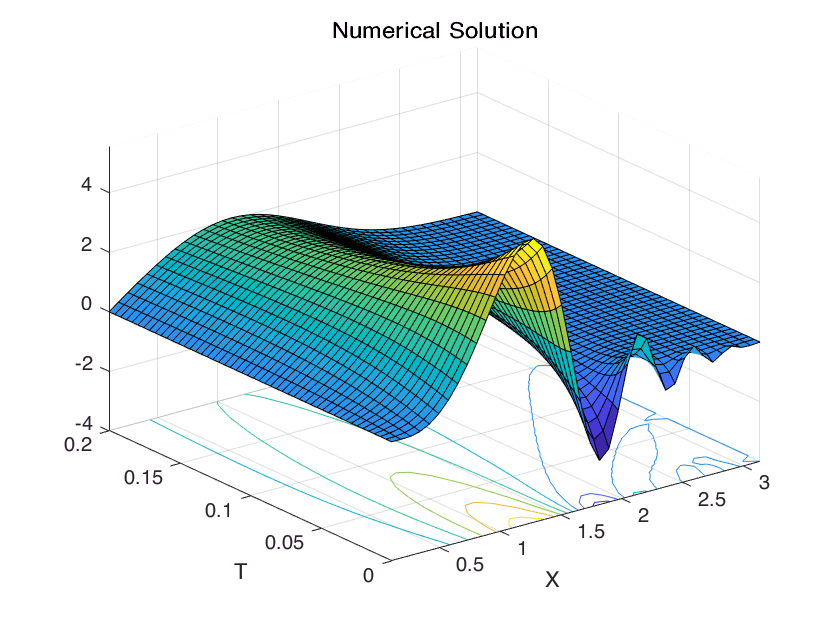

f = @(t, x)(0*x*t);

% 5 points Forward_Euler
[Nu1, k1] = FD_Heat_1D(ua, ub, ut, f, x, t, N_b, N_t, p_x, p_t, 1);

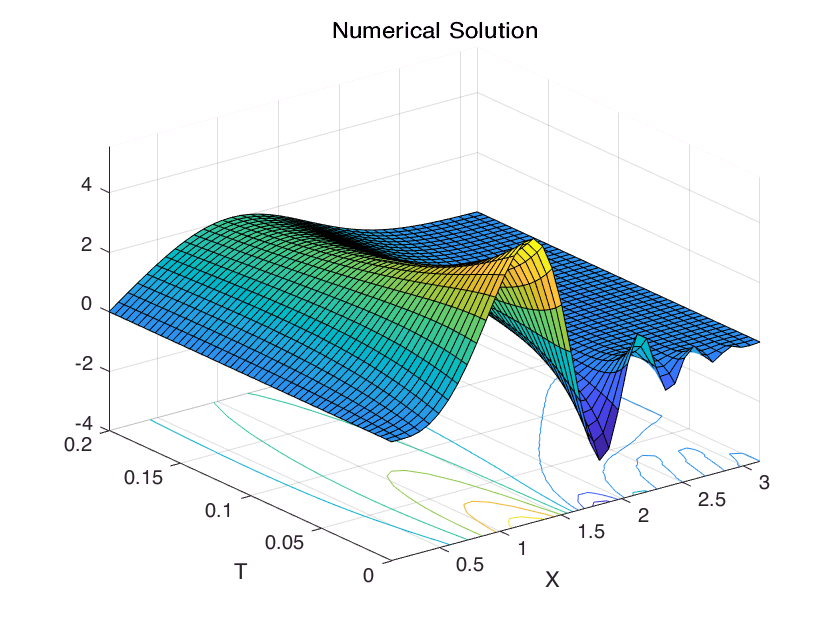


% 3 points Back_Euler
[Nu2, k2] = FD_Heat_1D(ua, ub, ut, f, x, t, N_b, N_t, p_x, p_t, 2);

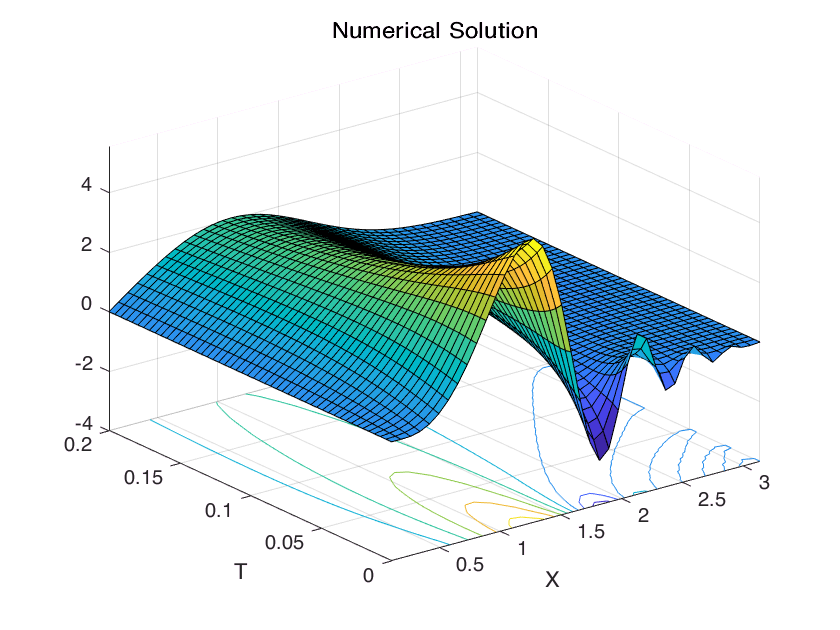


% C_N
[Nu3, k3] = FD_Heat_1D(ua, ub, ut, f, x, t, N_b, N_t, p_x, p_t, 3);